# Comparison of ERA5 Reanalysis with FINO1 Observations in the Marine ABL

## **Introduction**

This Live Script illustrates the processing and comparison of wind speed and friction velocity data from two sources:

- **ERA5 reanalysis data** from the European Centre for Medium-Range Weather Forecasts (ECMWF)

- **Sonic anemometer measurements** at the FINO1 offshore platform in the North Sea

The script supports the analysis presented in:

**Cheynet, E., Bogunovic Jakobsen, J., & Reuder, J. (2018).***Velocity spectra and coherence estimates in the marine atmospheric boundary layer*.Boundary-Layer Meteorology, 169, 429–460. DOI: 10.1007/s10546-018-0382-2 [Accepted version on NORA](https://hdl.handle.net/11250/3040299)

The FINO1 dataset contains two years of continuous high-frequency measurements from 2007–2008, used to investigate the marine atmospheric boundary layer (ABL), with a focus on turbulence modeling and similarity theory.

## Objective

The goal of this example is to:

- **Interpolate ERA5 data** to the FINO1 site

- **Filter observational data** by wind speed and direction

- **Compare**:

- Mean wind speed from ERA5 (extrapolated to 80 m) and FINO1 (measured at 80 m)

- Friction velocity u∗� estimated from ERA5 and FINO1

- **Quantify agreement** using correlation coefficient and bias

- **Visualize** time series for both variables

This allows us to assess the performance of ERA5 data in capturing key flow properties relevant to wind engineering and wind energy.

`Wind`** Structure – Key Fields Explained**

- `time`→ Time vector corresponding to starting time of the time series (in MATLAB `datenum` format)

- `z`→ Measurement heights above sea level [80, 60, 40] m

- `Nsamples`→ Number of samples, e.g. 720 means 720 time series of 60 min were used

- `U`→ Mean horizontal wind speed at each height, computed as $U=\sqrt{\bar{u}^2 + \bar{v}^2}$

- `meanT`→ Mean sonic (virtual) temperature at each height

- `meanDir`→ Mean wind direction in degrees from North

- `stdU`→ Standard deviation of streamwise (along-wind) velocity fluctuations, σu�

- `stdV`→ Standard deviation of lateral (cross-wind) velocity fluctuations, σv�

- `stdW`→ Standard deviation of vertical velocity fluctuations, σw

- `stdT`→ Standard deviation of sonic temperature fluctuations, σT�

- `zL`→ Non-dimensional stability parameter ζ=z/L, used for MOST classification

- `L`→ Obukhov length L, representing buoyancy-driven stability in the surface layer

- `u_star`→ Friction velocity u∗�, characterizing turbulent momentum flux

- `T_star`→ Temperature scale T∗�, used in similarity scaling 

- `wT`→ Turbulent heat flux $\overline{w'T'}$, 

- `uw`→ Reynolds shear stress $\overline{u'w'}$, 

- `vw`→ Reynolds stress $\overline{v'w'}$ 

- `Result_RA`→ Stationarity flag (1 = stationary, 0 = non-stationary)

- `Su`→ Power spectral density of streamwise velocity fluctuations, Su(f)

- `f`→ Frequency vector (Hz) associated with the spectral estimates

- `Sv`→ Power spectral density of lateral velocity fluctuations, Sv(f)

- `Sw`→ Power spectral density of vertical velocity fluctuations, Sw(f)

- `Suw`→ Co-spectrum Re[Suw(f)] i.e., frequency-resolved momentum flux

## Data processing

Specify the latitude and longitude of the FINO1 offshore platform. These coordinates are used to extract ERA5 data at the site location. 

Load 100-m zonal (`u100`) and meridional (`v100`) wind components from ERA5. Compute wind speed magnitude and interpolate it to the FINO1 location.

clearvars;close all;clc;
targetLat = [54.014861]; % target latitude
targetLon = [6.587639];  % target longitude


filename1 = "./dataAnalysed/data1.nc";

lat = ncread(filename1,'latitude');
lon = ncread(filename1,'longitude');
u100 = ncread(filename1,'u100');
v100 = ncread(filename1,'v100');
time1 = datetime(1970,1,1) + seconds(ncread(filename1,'valid_time'));

% Compute wind speed magnitude at each grid point
H = sqrt(u100.^2 + v100.^2);

% Create spatial grid for interpolation
[x, y] = meshgrid(lat, lon);

% Interpolate ERA5 wind speed at 100 m to FINO1 location
u = zeros(size(time1));
for ii = 1:numel(time1)
    F = scatteredInterpolant(x(:), y(:), reshape(H(:,:,ii),[],1));
    u(ii) = F(targetLat, targetLon);
end

Load surface friction velocity from ERA5 and interpolate it to the FINO1 site.

filename2 = "./dataAnalysed/data2.nc";

uS = ncread(filename2, 'zust');  % ERA5 surface friction velocity
time2 = datetime(1970,1,1) + seconds(ncread(filename2,'valid_time'));

% Interpolate u* at FINO1
u_star_ERA5 = zeros(size(time2));
for ii = 1:numel(time2)
    F = scatteredInterpolant(x(:), y(:), reshape(uS(:,:,ii),[],1));
    u_star_ERA5(ii) = F(targetLat, targetLon);
end

Load wind statistics from FINO1 and apply filters based on wind speed, direction, and stationarity.Extract velocity variances, friction velocity, and the Monin-Obukhov stability parameter ζ=z/L

data = dir('./dataAnalysed/Wind_statistics_*_PF1.mat');
z = [81.5, 61.5, 41.5];               % Measurement heights (m)
minU = 5; maxU = 30;                  % Wind speed filter range
Dir1 = 90; Dir2 = 180;                % Direction filter (SE sector)

% Initialize arrays
eta = []; Su = []; Sv = []; Sw = []; Suw = []; Utot = [];
stdU = []; stdV = []; stdW = []; u_star_FINO1 = [];
Dir = []; L = []; time_FINO1 = []; Result_RA = [];

% Loop over days and apply filters
for iDay = 1:numel(data)
    load(['dataAnalysed/',data(iDay).name],'Wind');

    indU = find(Wind.U(1,:) >= minU & Wind.U(1,:) < maxU & ...
                (Wind.meanDir(1,:) >= Dir2 | Wind.meanDir(1,:) <= Dir1) & ...
                Wind.Result_RA(1,:) == 1);

    % Concatenate selected samples
    eta = [eta, Wind.zL(:,indU)];
    Suw = [Suw, Wind.Suw(:,indU,:)];
    L = [L, Wind.L(indU)];
    Su = [Su, Wind.Su(:,indU,:)];
    Sv = [Sv, Wind.Sv(:,indU,:)];
    Sw = [Sw, Wind.Sw(:,indU,:)];
    Result_RA = [Result_RA, Wind.Result_RA];
    Dir = [Dir, Wind.meanDir(:,indU,:)];
    Utot = [Utot, Wind.U(:,indU)];
    stdU = [stdU, Wind.stdU(:,indU)];
    stdV = [stdV, Wind.stdV(:,indU)];
    stdW = [stdW, Wind.stdW(:,indU)];
    u_star_FINO1 = [u_star_FINO1, Wind.u_star(:,indU)];
    time_FINO1 = [time_FINO1, datetime(Wind.time(indU)', 'ConvertFrom', 'datenum')];
end

disp(Wind)

         time: [377×1 double]
            z: [80 60 40]
     Nsamples: 377
            U: [3×377 double]
        meanT: [3×377 double]
      meanDir: [3×377 double]
         stdU: [3×377 double]
         stdV: [3×377 double]
         stdW: [3×377 double]
         stdT: [3×377 double]
           zL: [3×377 double]
            L: [3×377 double]
       u_star: [3×377 double]
       T_star: [3×377 double]
           wT: [3×377 double]
           uw: [3×377 double]
           vw: [3×377 double]
    Result_RA: [3×377 double]
           Su: [3×377×52 double]
            f: [52×1 double]
           Sv: [3×377×52 double]
           Sw: [3×377×52 double]
          Suw: [3×377×52 double]



## Compare Wind Speed at 80 m: ERA5 vs FINO1

Extrapolate ERA5 wind speed to 80 m using a power law and compare to FINO1 sonic measurements at 80 m.

Compute correlation and bias after filtering ERA5 wind speed < 5 m/s.

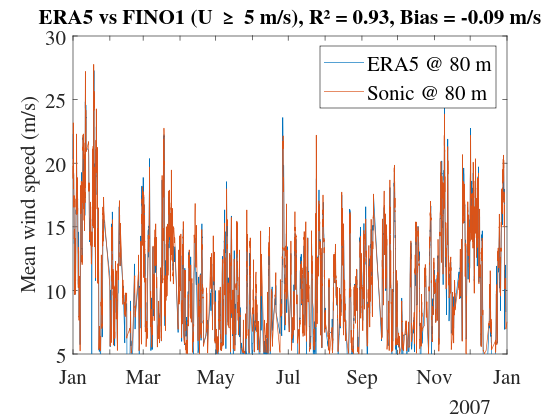

% figure('position', [100 500 1400 500])
figure
% Power-law extrapolation from 100 m to 80 m
u_80 = u(:)' * (80 / 100)^0.08;
% Interpolate to FINO1 time base (centered at +30 min)
u_80_interp = interp1(time1(:)', u_80, time_FINO1 + seconds(1800), 'linear');
% Apply validity mask
valid = u_80_interp >= 5 & ~isnan(u_80_interp) & ~isnan(Utot(1,:));
% Correlation and bias
R = corr(u_80_interp(valid)', Utot(1,valid)');
bias = mean(u_80_interp(valid)' - Utot(1,valid)');
% Plot results
plot(time_FINO1, u_80_interp, 'DisplayName', 'ERA5 @ 80 m')
hold on
plot(time_FINO1, Utot(1,:), 'DisplayName', 'Sonic @ 80 m')
ylabel('Mean wind speed (m/s)')
legend
title(sprintf('ERA5 vs FINO1 (U ≥ 5 m/s), R² = %.2f, Bias = %.2f m/s', R^2, bias))
xlim([datetime(2007,1,1), datetime(2008,1,1)])
ylim([5 30])
set(gcf, 'color', 'w')
set(findall(gcf,'-property','FontSize'), 'FontSize', 16, 'FontName', 'Times')

## Compare Friction Velocity: ERA5 vs FINO1

Adjust ERA5 surface friction velocity to 60 m height using a parametric decay model. Compare against averaged sonic-derived u∗ and compute statistical agreement.

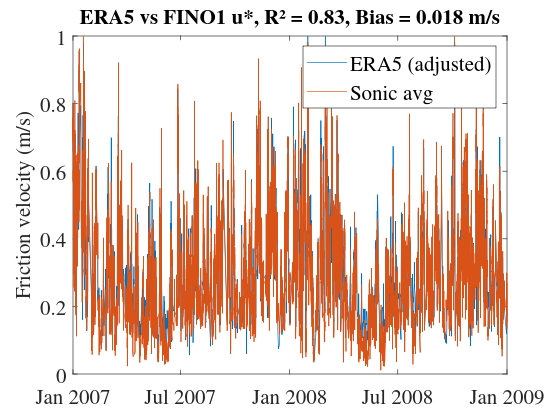

% figure('position', [100 500 1400 500])
figure
% Interpolate ERA5 u* to FINO1 timestamps (offset by +30 min)
u_star_ERA5_interp = interp1(time2(:), u_star_ERA5(:), time_FINO1 + seconds(1800), 'linear');

% Adjust ERA5 u* from surface to 60 m: u*(z) = u*_surf * (1 - z/h)^1.5
u_star_ERA5_interp = u_star_ERA5_interp .* (1 - 60/750)^1.5;

% Median over the three sonic levels
u_star_FINO1_averaged = median(u_star_FINO1, 'omitnan');

% Apply mask
valid = ~isnan(u_star_ERA5_interp) & ~isnan(u_star_FINO1_averaged(1,:));

% Correlation and bias
R = corr(u_star_ERA5_interp(valid)', u_star_FINO1_averaged(1,valid)');
bias = mean(u_star_ERA5_interp(valid) - u_star_FINO1_averaged(1,valid));

% Plot comparison
plot(time_FINO1, u_star_ERA5_interp, 'DisplayName', 'ERA5 (adjusted)')
hold on
plot(time_FINO1, u_star_FINO1_averaged, 'DisplayName', 'Sonic avg')
ylabel('Friction velocity (m/s)')
legend
title(sprintf('ERA5 vs FINO1 u*, R² = %.2f, Bias = %.3f m/s', R^2, bias))
xlim([datetime(2007,1,1), datetime(2009,1,1)])
ylim([0 1])
set(gcf, 'color', 'w')
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 16, 'FontName', 'Times')